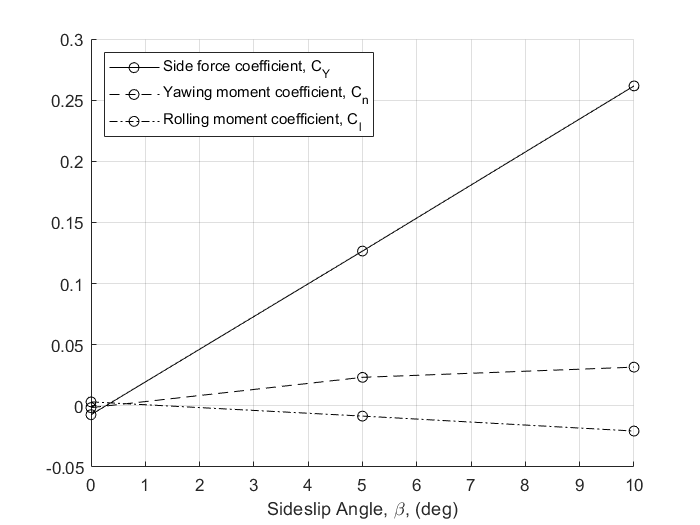

clear all; clc

% Data settings
Speed = 10;
RPM = 6;
%
% Speed = 15;
% RPM = 8;
% 
% Speed = 20;
% RPM = 10;

% Aircraft Geometry
S = 0.03469846; %m^2 (1578 ft^2/65^2)
b = 0.55332923; %m (118 ft/65)

% Atmospheric Conditions
rho = 1.21; %kg/m^3


beta = [0,5,10];

for i = 1:length(beta)

    % Get file names
    fileName = "u_"+ string(Speed) + "_a0_b" + string(beta(i))+ "_r" + string(RPM) + ".mat";
        
    x = load (fileName);
    
    % Get CY, Cn, Cl
    CY(i) = (x.Fy) / (0.5*rho*x.V^2*S);
    Cn(i) = (x.Tz) / (0.5*rho*x.V^2*S*b);
    Cl(i) = (x.Tx) / (0.5*rho*x.V^2*S*b);
    
    clear x fileName;
end

% Side force, Yaw moment, Rolling moment vs. Sideslip angle
figure

hold on
plot(beta, CY,'-ok')
plot(beta, Cn,'--ok')
plot(beta, Cl,'-.ok')
hold off

xlabel('Sideslip Angle, \beta, (deg)')
grid on 

legend('Side force coefficient, C_{Y}', 'Yawing moment coefficient, C_{n}', 'Rolling moment coefficient, C_{l}','Location','northwest')